% Adjust the value of e here
e = 1.20648;

init = [0, 1]; % Initial conditions psi(u=0), psi'(u=0)
uMax = 2; % Maximum u to solve for
uReport = uMax; % Value of u to report psi at


% ODE SOLVER
opts = odeset('RelTol',1e-12,'AbsTol',1e-12); % Accuracy
[u,soln] = ode45(@ourderivatives, [0 uMax], init, opts, e); % Solve the ODE

% PROBLEM OUTPUT
result=interp1(u,soln(:,1), uReport);
texte=num2str(e,12);
disp(['For e = ',texte,', psi(',num2str(uReport),') = ',num2str(result)])

For e = 1.20648, psi(2) = 9.8977e-05


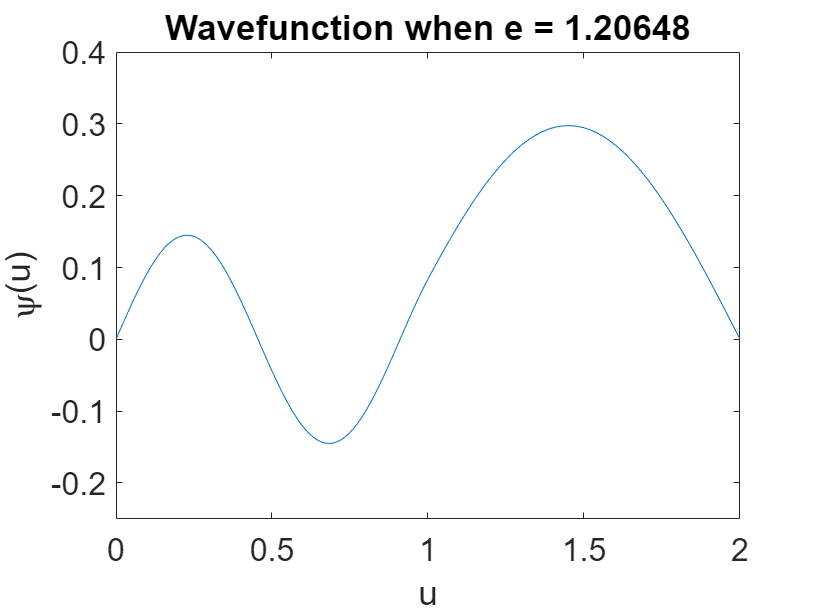

% Plot the solution
p = plot(u,soln(:,1));
p.Parent.FontSize = 16;
axis([0 uMax -0.25 0.4])
xlabel('u');
ylabel('\psi(u)');
title(['Wavefunction when e = ',texte]);


% POTENTIAL
% Call this function using f(u)
% f(u) = 0 for 0 <= u <= 1
% f(u) = 1 for 1 < u <= 2

function potential = f(u)
    u1 = (u>=0 & u<=1);    % [0, 1]
    u2 = (u>1 & u<=2);    % (1, 2]
    potential(u1) = 0;
    potential(u2) = 1;
end

% ODE DEFINITION - code your ODE here!!!
function derivatives = ourderivatives(u,psi,e)
    % psi(1) = psi(u), psi(2) = psi'(u)
    % derivatives = [psi'(u); psi''(u)];
    derivatives = [psi(2); 4*pi^2*psi(1)*(f(u)-e)];
end
